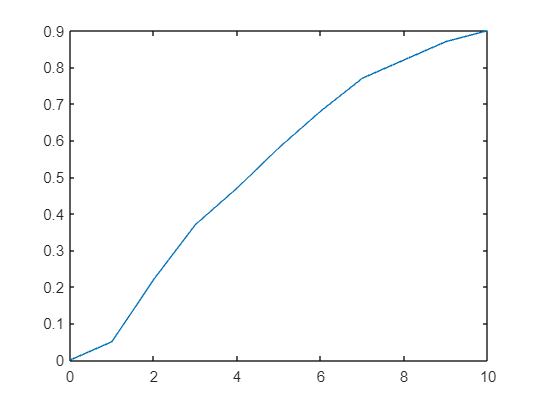

% Q6
clear all;clc;close all;
time = 0:10;
data = [0.0;0.05;0.22;0.37;0.47;0.58;0.68;0.77;0.82;0.87;0.90];
plot(time,data)

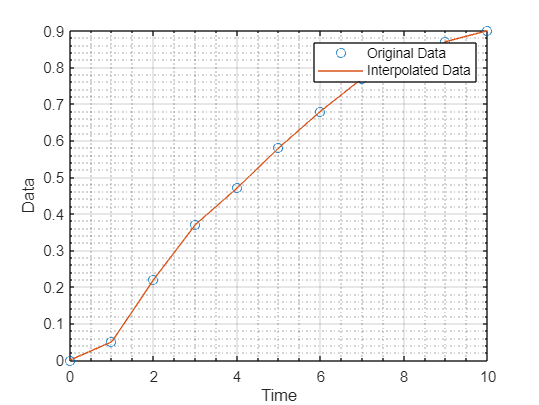



% Define the desired time points for interpolation
interpTime = 0:0.00001:10;

% Perform linear interpolation
interpData = interp1(time, data, interpTime, 'linear');

% Plot the original and interpolated data
plot(time, data, 'o', interpTime, interpData, '-');
legend('Original Data', 'Interpolated Data');
xlabel('Time');
ylabel('Data');
grid on

ax = gca;
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.XMinorGrid = 'on';
ax.YMinorGrid = 'on';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';

%The most shib
most_slope = (data(3)-data(2))/(time(3)-time(2))

most_slope = 0.1700

slope1 = 0;
y_inf = 1;
A = [slope1, -1; most_slope, -1];
b = [-y_inf; -(-0.12)];
intersectionPoint = linsolve(A, b);
tau1 = (intersectionPoint(1))

tau1 = 6.5882

k1 = y_inf

k1 = 1


%------------------------------------------------------
% Target y-value
target_y = 0.63*y_inf;

% Find the index of the closest y-value
[~, index] = min(abs(interpData - target_y));

% Get the corresponding x-value
tau2 = interpTime(index)

tau2 = 5.5000

k2 = y_inf

k2 = 1

%------------------------------------------------------
% Target y-value
target_y_2 = 0.28*y_inf;

% Find the index of the closest y-value
[~, index2] = min(abs(interpData - target_y_2));

% Get the corresponding x-value
tau3 = 1.5*(tau2 - interpTime(index2))

tau3 = 4.6500

k3 = y_inf

k3 = 1

% Create a list with 1 repeated 10 times
u = repmat(1, 1, 10)

u =      1     1     1     1     1     1     1     1     1     1


u = [0.5 u]

u =     0.5000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


PHI = [];
phi0 = [0 0];
PHI = [PHI;phi0];
for i = 1 : 10
    phi = [-data(i-1+1) u(i-1+1)];
    PHI = [PHI;phi];

end
PHI_transpose = PHI.';
theta = (inv(PHI_transpose*PHI))*PHI_transpose*data(1:11);
a1 = theta(1);
b1 = theta(2);
tau_LS = 1/(1+a1)

tau_LS = 6.9452

k_LS = b1/(1+a1)

k_LS = 1.1791

figure
s = tf('s');
Numerator = [k_LS];
Denom = [tau_LS 1];
G_estimated = tf(Numerator,Denom)

G_estimated =
 
     1.179
  -----------
  6.945 s + 1
 
Continuous-time transfer function.
Model Properties


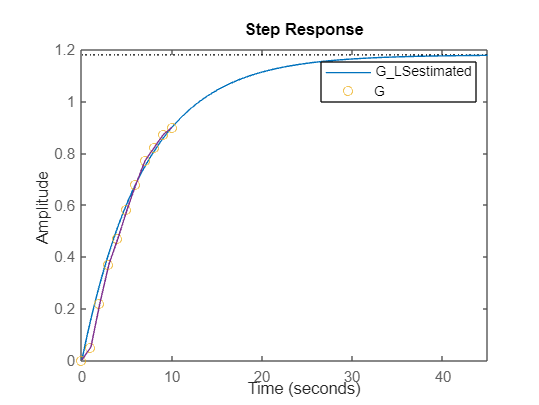

[Y_LSestimated,~] = step(G_estimated,time);
step(G_estimated)
hold on
plot(time, data, 'o', interpTime, interpData, '-');
legend("G_LSestimated","G")

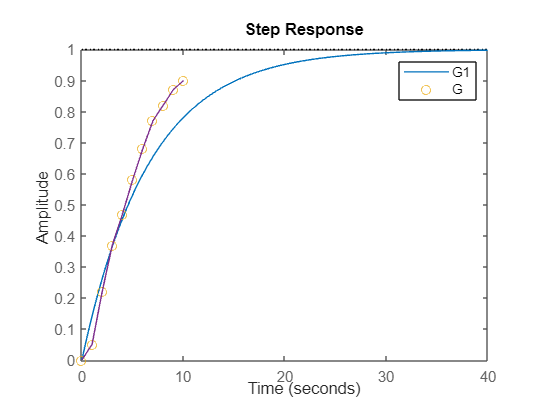

G1 = tf([k1],[tau1 1]);
G2 = tf([k2],[tau2 1]);
G3 = tf([k3],[tau3 1]);
figure
[Y1,~] = step(G1,time);
step(G1)
hold on
plot(time, data, 'o', interpTime, interpData, '-');
legend("G1","G")

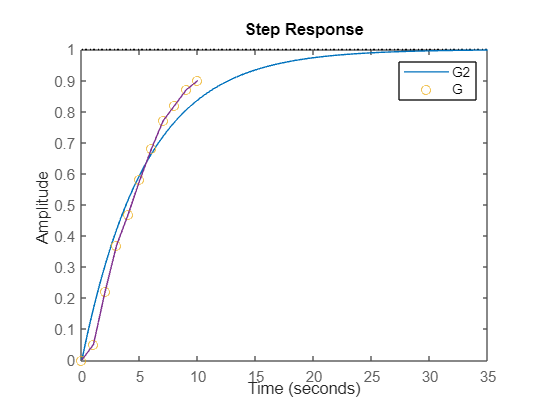



figure
[Y2,~] = step(G2,time);
step(G2)
hold on
plot(time, data, 'o', interpTime, interpData, '-');
legend("G2","G")

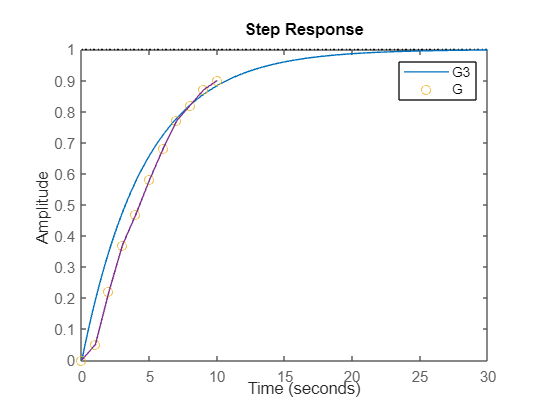


figure
[Y3,~] = step(G3,time);
step(G3)
hold on
plot(time, data, 'o', interpTime, interpData, '-');
legend("G3","G")

e1 = MSE(time.',Y1,data)

e1 = 0.0069

e2 = MSE(time.',Y2,data)

e2 = 0.0036

e3 = MSE(time.',Y3,data)

e3 = 0.0062

e4 = MSE(time.',Y_LSestimated,data)

e4 = 0.0021

function e = MSE(T,Y,Y_test)
    e = 0 ;
    for i = 1:length(T)
        e = e + (Y(i)-Y_test(i))^2;
    end
    e = e/length(T);
end